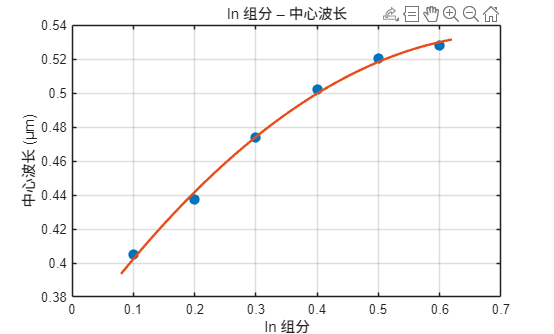

%% 数据
In = [0.1 0.2 0.3 0.4 0.5 0.6];          % In 组分
lambda = [0.40496 0.43718 0.4737 0.50179 0.5204 0.52814];  % 中心波长 (µm)
width  = [0.03027 0.04807 0.07551 0.10955 0.13937 0.1739]; % 光谱宽度 (µm)

%% 拟合（二次多项式已足够，如需更高阶自行改数字）
p_lambda = polyfit(In,lambda,2);   % 中心波长拟合
p_width  = polyfit(In,width,2);    % 宽度拟合

lambda_fit = polyval(p_lambda,In);
width_fit  = polyval(p_width,In);

%% 绘图
figure('Units','centimeters','Position',[5 5 16 6]);

figure;
scatter(In,lambda,60,'filled','MarkerFaceColor',[0 0.45 0.74]);
hold on
fplot(@(x) polyval(p_lambda,x),[0.08 0.62],'LineWidth',1.8,'Color',[0.9 0.3 0.1])
xlabel('In 组分'); ylabel('中心波长 (µm)');
title('In 组分 – 中心波长');
grid on; box on;

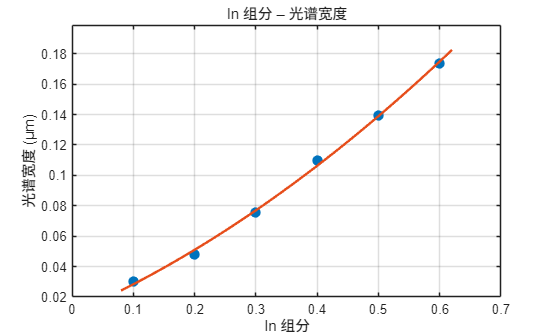


figure;
scatter(In,width,60,'filled','MarkerFaceColor',[0 0.45 0.74]);
hold on
fplot(@(x) polyval(p_width,x),[0.08 0.62],'LineWidth',1.8,'Color',[0.9 0.3 0.1])
xlabel('In 组分'); ylabel('光谱宽度 (µm)');
title('In 组分 – 光谱宽度');
grid on; box on;


%% 把拟合公式打印出来
fprintf('\n-------- 拟合结果 --------\n');


-------- 拟合结果 --------


fprintf('中心波长  λ(x) = %.4f·x² + %.4f·x + %.4f  (µm)\n',p_lambda);

中心波长  λ(x) = -0.3465·x² + 0.4979·x + 0.3560  (µm)


fprintf('光谱宽度  w(x)  = %.4f·x² + %.4f·x + %.4f  (µm)\n',p_width);

光谱宽度  w(x)  = 0.1664·x² + 0.1767·x + 0.0090  (µm)



%% 趋势总结
fprintf('\n-------- 趋势总结 --------\n');


-------- 趋势总结 --------


fprintf('1. In 组分升高，中心波长呈"上凸"增大，但增速逐渐放缓（二次项系数为正但较小）。\n');

1. In 组分升高，中心波长呈"上凸"增大，但增速逐渐放缓（二次项系数为正但较小）。


fprintf('2. In 组分升高，光谱宽度近似抛物线增宽，开口向上，增宽速率越来越快。\n');

2. In 组分升高，光谱宽度近似抛物线增宽，开口向上，增宽速率越来越快。


fprintf('3. 当前数据范围内未见饱和或下降迹象，可外推至 ~0.65，但更高组分需验证。\n');

3. 当前数据范围内未见饱和或下降迹象，可外推至 ~0.65，但更高组分需验证。
